## 2-D Affine Transformations

clear all; close all;

## Transformations

Scaling

S = [ 2 0;
      0 1 ]

S =      2     0
     0     1


## Translation vector

t = [ 2; 
      3]

t =      2
     3


  
% % Shear
% G = [ 1.0 0.5; 
%       0.0 1.0 ];
% 
% Rotation
theta = pi/8; 
R = [ cos(theta) -sin(theta);
      sin(theta)  cos(theta) ];

## The shape to be transformed

Rectangle given by four vertices

px = [0 4 4 0];   % x-coords
py = [0 0 2 2];   % y-coords  
disp('Input shape')

Input shape


X  = [px;py]        % Matrix containing the 2-D points.

X =      0     4     4     0
     0     0     2     2


## Apply transformation to shape

X_p = (S * R) * X + t; 

disp('Transformed shape')

Transformed shape


X_p

X_p =     2.0000    9.3910    7.8603    0.4693
    3.0000    4.5307    6.3785    4.8478


## Display shapes

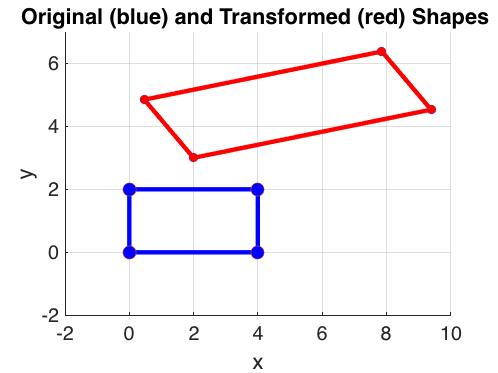

figure;
hold on;
axis([ -2 10 -2 7 ] );
% Repeating the first vertex to close polygon lines
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'b-', 'linewidth',4);
plot([X(1,:) X(1,1)], [X(2,:) X(2,1)], 'o', 'MarkerSize', 12, 'MarkerFaceColor','b')
xlabel('x','FontSize',30);
ylabel('y','FontSize',30);
set(gca, 'fontsize',18);
set(gcf, 'color', 'w' );
title('Original (blue) and Transformed (red) Shapes ');
% Show the transformed points
plt = plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'r-', 'linewidth',4);
plot([X_p(1,:), X_p(1,1)], [X_p(2,:), X_p(2,1)], 'o', 'MarkerSize', 8, 'MarkerFaceColor','r');
% Plot transformed shape transparent
plt.Color(4) = 0.5;
grid on;